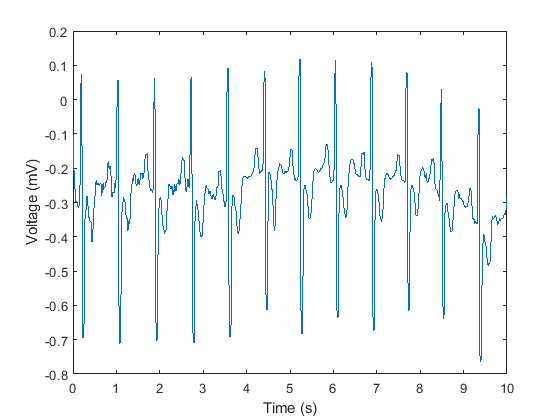

%% function by user "Said BOUREZG" to convert .dat and plot ECG signal
clear all
clc
close all
[filename, pathname] = uigetfile('*.dat', 'Open file .dat');% only image Bitmap
if isequal(filename, 0) || isequal(pathname, 0)   
    disp('File input canceled.');  
   ECG_Data = [];  
else
fid=fopen(filename,'r');
end
time=10;
f=fread(fid,2*360*time,'ubit12');
Orig_Sig=f(1:2:length(f));
t=1:length(Orig_Sig);
t=(10/3600).*t;
Orig_Sig=(Orig_Sig-960)/500;
Filt_Sig = medfilt1(Orig_Sig,12);
plot(t, Filt_Sig)
xlabel('Time (s)');
ylabel('Voltage (mV)');

### Check for tachycardia (faster than normal)

% Tachycardia is when an adult has a resting heart beat greater than 100
% beats per minute
condition=0;
BPM=length(findpeaks(Filt_Sig,'MinPeakHeight',0.20))*6;

[~,T]=findpeaks(Filt_Sig,'MinPeakHeight',0.15);

T=(10/3600).*T;
if BPM>100
    fprintf('This patient is at risk of tachycardia');
    condition=1;   
end

### **Check for Atrial Premature Contraction (APC)**

for ii=1:length(T)-1
    if T(ii+1)-T(ii)<0.4
            fprintf('This patient is at risk Atrial Premature Contraction');
            condition=1;
            break
    end
end

### Check for Premature Ventricular Contraction (PVC)

% Flip the Filtered Signal Graph in order to find troughs of ECG
Flip_Sig=-Filt_Sig;
[~,negT]=findpeaks(Flip_Sig,'MinPeakHeight',0.15);
negT=(10/3600).*negT;
for jj=1:length(negT)
    if T(jj)-negT(jj)<0.2
         fprintf('This patient is at risk Premature Ventricular Contraction');
         condition=1;
         break
    end
end

Index exceeds the number of array elements (0).

### Check for bradycardia (slower than normal)

% Bradycardia is when an adult has a resting heart beat less than 50 beats
% per minute
if BPM<50
    fprintf('This patient is at risk of bradycardia');
    condition=1;
end

### Check if the patient is healthy

if condition==0
    fprintf('This patient is not at risk of arrthymia');
end